# Spectral Comparison of Display Primaries

12/1/2022

## PSRN and SAM

### Generate table

disp_name = ["NEC"; "HP"; "Rift"];

load('compare_RGB_primaries_result_nec')
psnr_rgb_nec = [psnr(s_predicted_r.amplitude,mea_r.amplitude) psnr(s_predicted_g.amplitude,mea_g.amplitude) psnr(s_predicted_b.amplitude,mea_b.amplitude)];
sam_rgb_nec = [sam(s_predicted_r.amplitude,mea_r.amplitude) sam(s_predicted_g.amplitude,mea_g.amplitude) sam(s_predicted_b.amplitude,mea_b.amplitude)];

load('compare_RGB_primaries_result_hp')
psnr_rgb_hp = [psnr(s_predicted_r.amplitude,mea_r.amplitude) psnr(s_predicted_g.amplitude,mea_g.amplitude) psnr(s_predicted_b.amplitude,mea_b.amplitude)];
sam_rgb_hp = [sam(s_predicted_r.amplitude,mea_r.amplitude) sam(s_predicted_g.amplitude,mea_g.amplitude) sam(s_predicted_b.amplitude,mea_b.amplitude)];

load('compare_RGB_primaries_result_rift')
psnr_rgb_rift = [psnr(s_predicted_r.amplitude,mea_r.amplitude) psnr(s_predicted_g.amplitude,mea_g.amplitude) psnr(s_predicted_b.amplitude,mea_b.amplitude)];
sam_rgb_rift = [sam(s_predicted_r.amplitude,mea_r.amplitude) sam(s_predicted_g.amplitude,mea_g.amplitude) sam(s_predicted_b.amplitude,mea_b.amplitude)];

psnr_t = [psnr_rgb_nec; psnr_rgb_hp; psnr_rgb_rift];
psnr_table = array2table(psnr_t,'VariableNames',{'R','G','B'},'RowName',{'NEC','HP','Rift'});
psnr_table

psnr_table = 3×3 table
              R         G         B   
            ______    ______    ______

    NEC     84.218    91.583    98.707
    HP      84.235    86.958    95.938
    Rift     88.76     93.34    95.798


Matlab2latex.table2latex(psnr_table)

sam_t = [sam_rgb_nec; sam_rgb_hp; sam_rgb_rift];
sam_t = rad2deg(sam_t);
sam_table = array2table(sam_t,'VariableNames',{'R','G','B'},'RowName',{'NEC','HP','Rift'});

sam_table

sam_table = 3×3 table
              R         G         B   
            ______    ______    ______

    NEC     2.2257    2.9987    2.3645
    HP      4.8175    3.4332    2.0135
    Rift    3.7291    2.3325    1.9986


save('psnr_sam_table','psnr_table','sam_table')


### Generate Latex

Matlab2latex.table2latex(sam_table)


## Generate plots

load('compare_RGB_primaries_result_nec')
whos;

  Name                 Size            Bytes  Class                                      Attributes

  a                    1x1                 8  matlab.graphics.illustration.Legend                  
  disp                 1x1                 8  NECPA271Sim                                          
  disp_name            3x1               258  string                                               
  g                    1x1                 8  matlab.ui.Figure                                     
  haxis                1x1                 8  matlab.graphics.axis.Axes                            
  hg                   1x1                 8  matlab.ui.Figure                                     
  i                    1x1                 8  double                                               
  idx                  1x1                 8  double                                               
  ind                  1x1                 8  double                                               

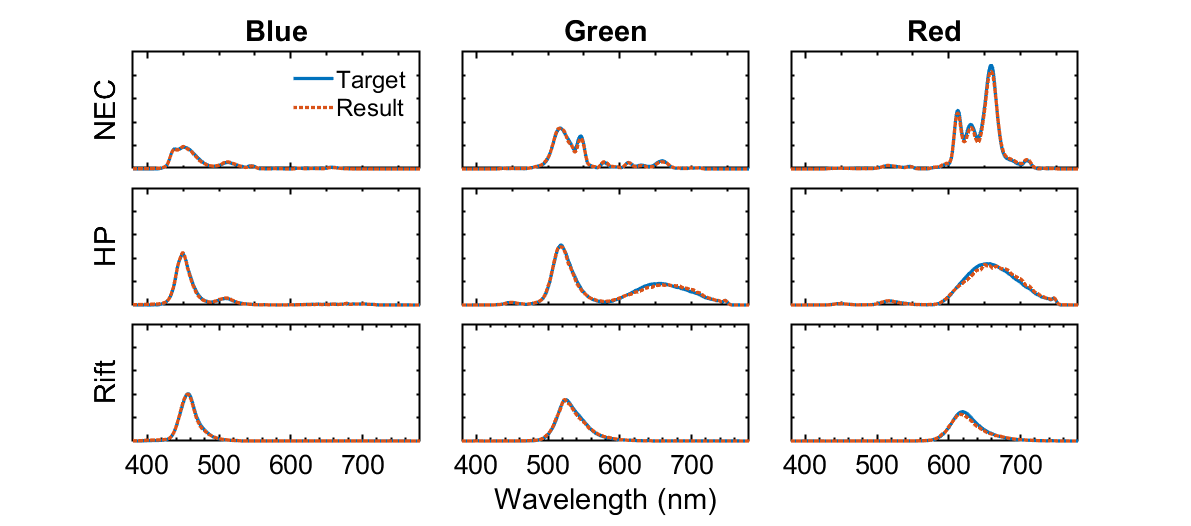

s_ref{1,1} = s_predicted_r;
s_ref{1,2} = s_predicted_g;
s_ref{1,3} = s_predicted_b;
s_mea{1,1} = mea_r;
s_mea{1,2} = mea_g;
s_mea{1,3} = mea_b;

load('compare_RGB_primaries_result_hp')
s_ref{2,1} = s_predicted_r;
s_ref{2,2} = s_predicted_g;
s_ref{2,3} = s_predicted_b;
s_mea{2,1} = mea_r;
s_mea{2,2} = mea_g;
s_mea{2,3} = mea_b;

load('compare_RGB_primaries_result_rift')
s_ref{3,1} = s_predicted_r;
s_ref{3,2} = s_predicted_g;
s_ref{3,3} = s_predicted_b;
s_mea{3,1} = mea_r;
s_mea{3,2} = mea_g;
s_mea{3,3} = mea_b;

clf
td = tiledlayout(3,3,'TileSpacing','compact');

hg = gcf;
set(hg,'Visible','on')

for i=1:3
    for j=1:3
        s1 = s_ref{i,j}.amplitude;
        s2 = s_mea{i,j}.amplitude;

        % order: B G R
        k = 4-j;
        idx = 1+(k-1)+3*(i-1);

        %haxis = subplot(3,3,idx);
        haxis = nexttile(idx);
        hold on
        plot(380:780,s1)
        plot(380:780,s2,':')
        axis([380 780 0 5e-3])
        PlotBeautify(haxis)
        legend off

        if idx < 7
            xticklabels({});
        end
        
        %if mod(idx,3)~=1
        yticklabels({});
        %end

        switch idx
            case 1
                ylabel('NEC')
            case 4
                ylabel('HP')
            case 7
                ylabel('Rift')
        end
        
        switch idx
            case 3
                title('Red')
            case 2
                title('Green')
            case 1
                title('Blue')
        end

        switch idx
            case 8
                xlabel('Wavelength (nm)')
        end

        switch idx
            case 1
                lgd = legend('Target','Result');
                lgd.Box = 'off';
        end
        
    end
end
hg.Position = [686 571 1191 526];
saveas(hg,'compare_RGB_primaries.png')